n=30:1:100;
a=2.378e+07;
b=-0.6566;
c=4151;
d=-0.07757;
y1=11.344*(a*exp(b.*n)+c*exp(d.*n));

p=1.7e-02;
l=62.8.*n;
s=0.125*pi;
rac_dc=2.5;
y2=20*p.*l./s;

y=y1+y2;
plot(n,y)
hold on
plot(n,y1)
hold on
plot(n,y2)
[minV,minInd]=min(y);
plot(n(minInd),y(minInd),'r*')
n(minInd)

ans = 54

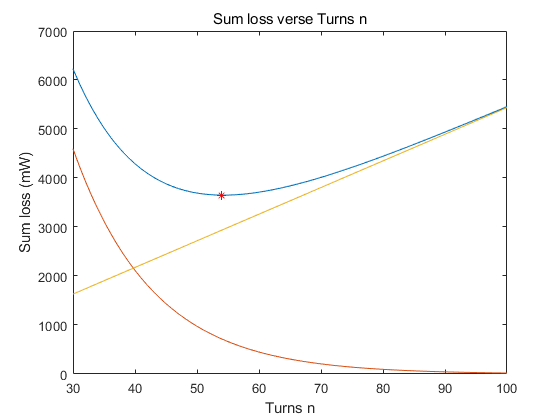

xlim([30 100])
%legend()
xlabel('Turns n') %设置横坐标轴
ylabel('Sum loss (mW)') %设置纵坐标轴
title('Sum loss verse Turns n')